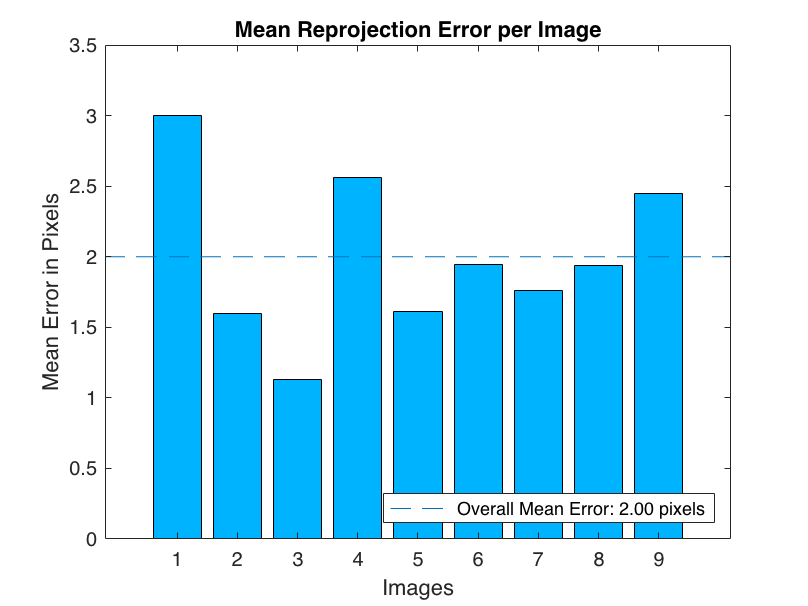

% Define images to process
imageFileNames = {'/Users/srividyaravipati/Desktop/assignment 1/Part C/cv images/board1.png',...
    '/Users/srividyaravipati/Desktop/assignment 1/Part C/cv images/board2.jpeg',...
    '/Users/srividyaravipati/Desktop/assignment 1/Part C/cv images/board3.jpeg',...
    '/Users/srividyaravipati/Desktop/assignment 1/Part C/cv images/board4.jpeg',...
    '/Users/srividyaravipati/Desktop/assignment 1/Part C/cv images/board5.jpeg',...
    '/Users/srividyaravipati/Desktop/assignment 1/Part C/cv images/board6.jpeg',...
    '/Users/srividyaravipati/Desktop/assignment 1/Part C/cv images/board7.jpeg',...
    '/Users/srividyaravipati/Desktop/assignment 1/Part C/cv images/board8.jpeg',...
    '/Users/srividyaravipati/Desktop/assignment 1/Part C/cv images/board9.jpeg',...
    };
% Detect calibration pattern in images
detector = vision.calibration.monocular.CheckerboardDetector();
[imagePoints, imagesUsed] = detectPatternPoints(detector, imageFileNames);
imageFileNames = imageFileNames(imagesUsed);

% Read the first image to obtain image size
originalImage = imread(imageFileNames{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates for the planar pattern keypoints
squareSize = 25;  % in units of 'millimeters'
worldPoints = generateWorldPoints(detector, 'SquareSize', squareSize);

% Calibrate the camera
[cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', false, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);

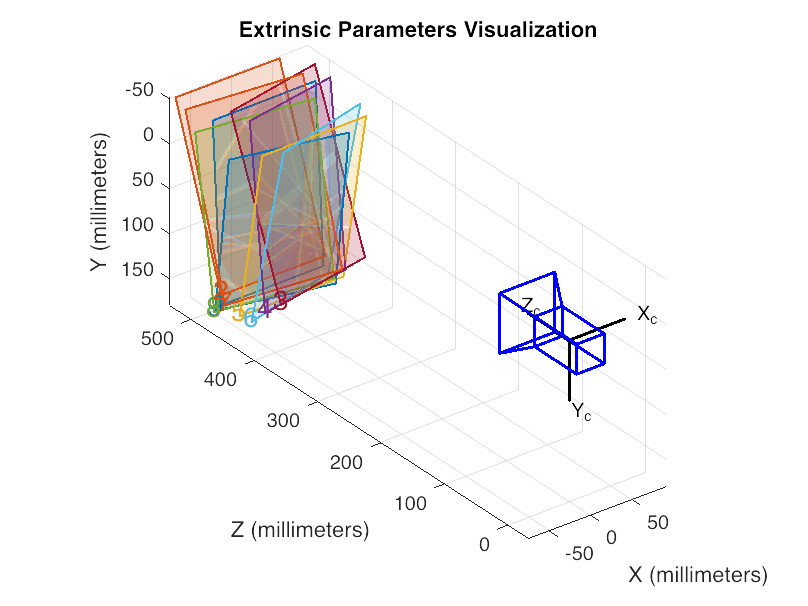


% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, cameraParams);


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [ 3021.1076 +/- 19.9989    3034.6989 +/- 20.2472 ]
Principal point (pixels):[  883.0715 +/- 5.8662      652.9829 +/- 11.6725 ]
Radial distortion:       [    0.0865 +/- 0.0220       -0.2137 +/- 0.0958  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.0487 +/- 0.0060       -0.0539 +/- 0.0057       -1.5690 +/- 0.0006  ]
                         [   -0.3028 +/- 0.0050       -0.2815 +/- 0.0047       -1.5514 +/- 0.0008  ]
                         [   -0.0973 +/- 0.0044       -0.4335 +/- 0.0041       -1.5670 +/- 0.0011  ]
                         [    0.0773 +/- 0.0042       -0.3129 +/- 0.0040       -1.5136 +/- 0.0009  ]
                         [    0.1432 +/- 0.0038        0.1582 +/- 0.0034       -1.5738 +/- 0.0005  ]
                         [    0.3456 +/- 0.0036       -0.0886 +/- 0.0032       -1.5030 +/- 0.0007  ]
 


% For example, you can use the calibration data to remove effects of lens distortion.
undistortedImage = undistortImage(originalImage, cameraParams);

% See additional examples of how to use the calibration data.  At the prompt type:
% showdemo('MeasuringPlanarObjectsExample')
% showdemo('StructureFromMotionExample')